# การเขียนโปรแกรมชั้นพื้นฐานในโปรแกรม MATLAB

โดย อาจารย์ ธนัชชา ชูพจน์เจริญ

# Basic Programming  in MATLAB

Author :  Thanacha Choopojcharoen

Copyright : Thanacha Choopojcharoen

## จุดประสงค์

เอกสารนี้จัดทำขึ้นเพื่ออธิบายถึงการใช้งานขั้นพื้นฐานของโปรแกม MATLAB ซึ่งผู้เรียนสามารถ

- ใช้งานเงื่อนไข (conditional statement)

- ใช้งาน for-loop และ while-loop

## 1) การเขียนเงื่อนไข

การเขียนเงื่อนไขใน MATLAB ประกอบไปด้วย logical statement ที่เป็นจริงหรือเป็นเท็จ ยกตัวอย่างเช่น


$$\sqrt{{\left(x-h\right)}^2 +{\left(y-k\right)}^2 }<r$$


จงสร้าง script ใหม่และเขียน code ดังต่อไปนี้

## 2) การเขียน loop

loop เป็นพื้นฐานสำคัญในการเขียนโปรแกรมต่างๆ ซึ่งมีองค์ประกอบหลักคือ ตัวแปรควบคุม loop หรือ loop-control variable

### 2.1) การเขียน for-loop 

เราสามารถกำหนดให้ loop-control variable เปลี่ยนค่าไปเรื่อยๆตามเวกเตอร์ที่กำหนดให้ 

loop แบบนี้เรียกว่า for-loop ซึ่งเหมาะที่จะใช้กับการเขียนโปรแกรมแบบ Recursion


$$\begin{array}{l}
y_{i+1} =y_i +y_i \left(1-y_i \right)\forall \;i=1,\cdots ,9\\
y_i =0\ldotp 1
\end{array}$$


หากการคำนวณในแต่ละขั้นตอนไม่ได้ขึ้นอยู่กับการคำนวณก่อนหน้านั้น เราควรที่จะใช้ vectorization แทนการเขียน for-loop เช่น


$$y_i =i^2 +\cos \left(i\right)\sin \left(i\right)$$


### 2.2) การเขียน while-loop 

บางครั้ง เราอาจต้องการให้โปรแกรมคำนวณไปเรื่อยจนกว่าจะตรงกับเงื่อนไขอะไรบางอย่าง 

loop แบบนี้เรียกว่า while-loop 

ในกรณีตัวอย่าง เราจะทำการคำนวณแบบเดียวกันกับ for-loop เพียงแต่ว่าเราจะหยุดคำนวณก็ต่อเมื่อค่านิ่งแล้ว

## โจทย์

### ข้อที่ 1

กำหนดให้สัญญาณมีการเปลี่ยนแปลงโดยเริ่มจากค่า 0 และเปลี่ยนไปยังค่า 1 ซึ่งเราจะเรียกค่า 1 ว่าค่าเป้าหมาย

เราจะนิยามให้ Settling time ของสัญญาณคือระยะเวลาที่สัญญาณเริ่มที่จะอยู่ภายใน 2% ของค่าสุดท้ายโดยไม่ที่ไม่ออกนอก 2%

จงเขียน script ที่ใช้ในการหา Settling time ของสัญญาณต่อไปนี้

t = (0:0.01:10)';
y = 1-exp(-1*t).*cos(2*pi*t)

y =          0
    0.0119
    0.0275
    0.0467
    0.0694
    0.0953
    0.1244
    0.1563
    0.1911
    0.2283


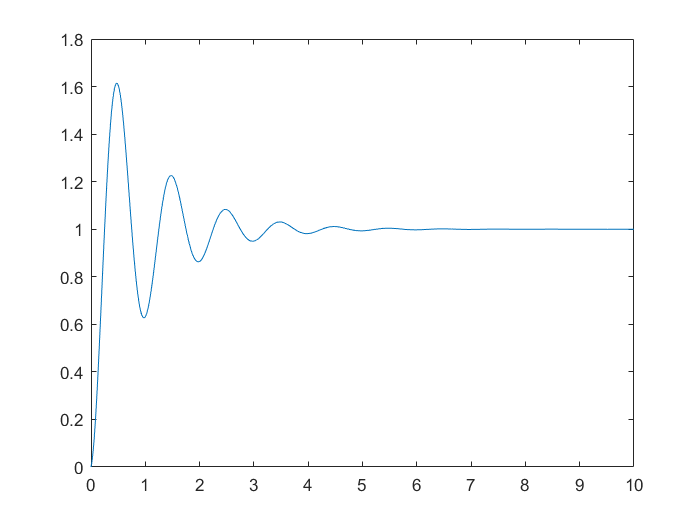

plot(t,y)


trig_plus = (102/100)*1

trig_plus = 1.0200

trig_minus = (98/100)*1

trig_minus = 0.9800

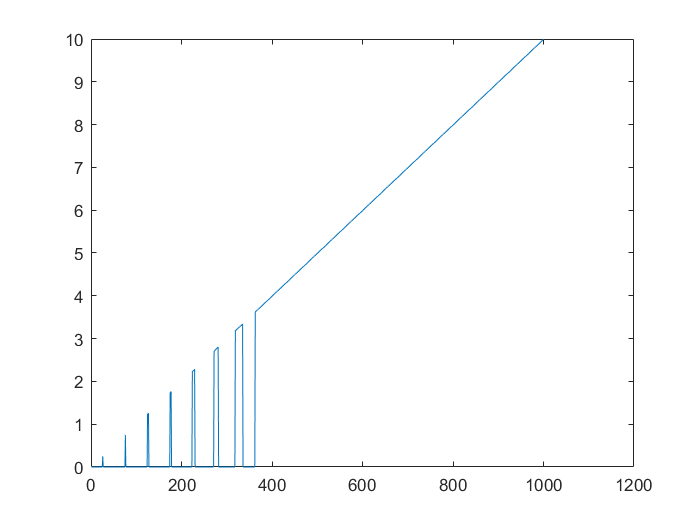


j = 1;
a = 1001;
b = zeros(a,1);
for i = 0:0.01:10
    if 1-exp(-1*i)*cos(2*pi*i) <= trig_plus && 1-exp(-1*i)*cos(2*pi*i) >= trig_minus
        b(j) = i;
    end
    j = j+1;
end
plot(b)

c = find(b == 0);
t = b(c(end)+1:end);

% t is answer